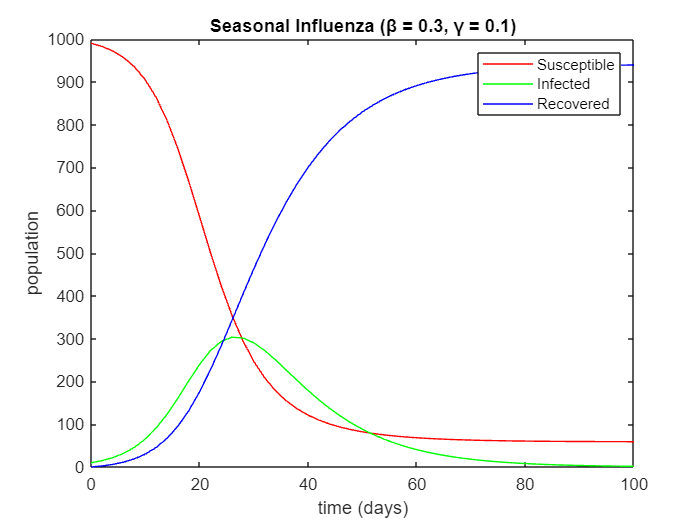

%Part 2

h = 2;
S0 = 990;
I0 = 10;
R0 = 0;
T0 = 0;
T = 100;

%influenza, COVID-19, Measeles
beta = [0.3,1,2]; 
gamma = [0.1,0.1,0.2];



influenza = modelSIR(S0,I0,R0,T0,T,h,beta(1),gamma(1));
COVID = modelSIR(S0,I0,R0,T0,T,h,beta(2),gamma(2));
measles = modelSIR(S0,I0,R0,T0,T,h,beta(3),gamma(3));


plot(influenza(1,:),influenza(2,:),'r',influenza(1,:),influenza(3,:),'g',influenza(1,:),influenza(4,:),'b')
xlabel('time (days)');
ylabel('population');
legend('Susceptible','Infected','Recovered');
title('Seasonal Influenza (β = 0.3, γ = 0.1)');

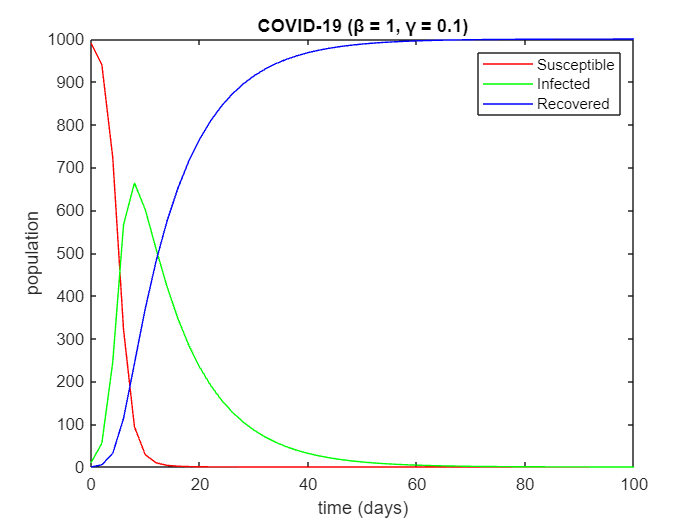


plot(COVID(1,:),COVID(2,:),'r',COVID(1,:),COVID(3,:),'g',COVID(1,:),COVID(4,:),'b')
xlabel('time (days)');
ylabel('population');
legend('Susceptible','Infected','Recovered');
title('COVID-19 (β = 1, γ = 0.1)');

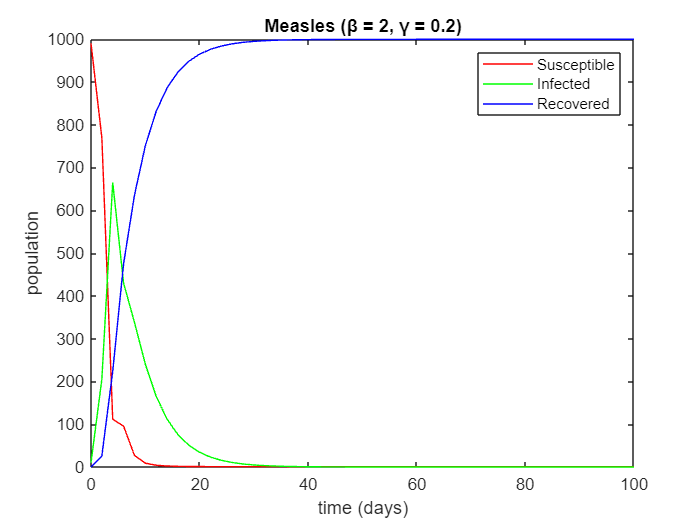


plot(measles(1,:),measles(2,:),'r',measles(1,:),measles(3,:),'g',measles(1,:),measles(4,:),'b')
xlabel('time (days)');
ylabel('population');
legend('Susceptible','Infected','Recovered');
title('Measles (β = 2, γ = 0.2)');

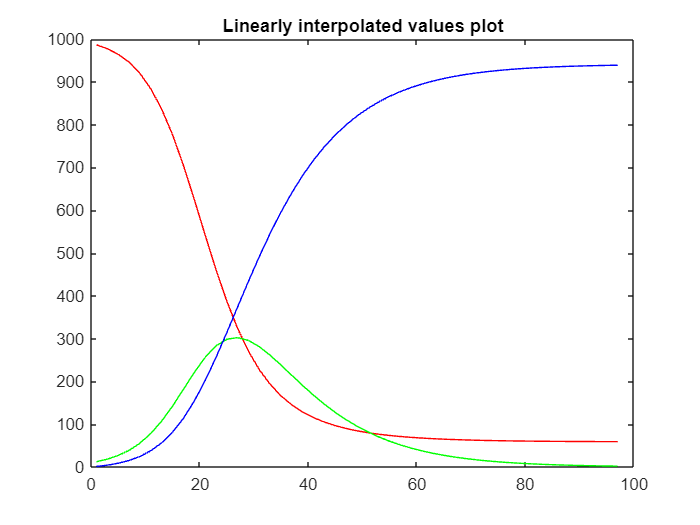


n = (T-T0)/h;
daysInter = 1:h:T;
susepInter = zeros(1,size(days,2)); 
infectInter = zeros(1,size(days,2));
recoverInter = zeros(1,size(days,2));

for i=1:n-1  % Linear Interpolation
    susepInter(i) = ((daysInter(1,i) - influenza(1,i+1))/(influenza(1,i) - influenza(1,i+1)))*influenza(2,i) + ((daysInter(1,i) - influenza(1,i))/(influenza(1,i+1) - influenza(1,i)))*influenza(2,i+1);
    infectInter(i) = ((daysInter(1,i) - influenza(1,i+1))/(influenza(1,i) - influenza(1,i+1)))*influenza(3,i) + ((daysInter(1,i) - influenza(1,i))/(influenza(1,i+1) - influenza(1,i)))*influenza(3,i+1);
    recoverInter(i) = ((daysInter(1,i) - influenza(1,i+1))/(influenza(1,i) - influenza(1,i+1)))*influenza(4,i) + ((daysInter(1,i) - influenza(1,i))/(influenza(1,i+1) - influenza(1,i)))*influenza(4,i+1);
end

plot(daysInter(1,1:49), susepInter, 'r')
hold on
plot(daysInter(1,1:49), infectInter, 'g')
plot(daysInter(1,1:49), recoverInter, 'b')
title("Linearly interpolated values plot")
hold off

EL2susepLinear = sqrt(sum((influenza(2,1:49)-susepInter).^2)./n)  % Error for susceptible (flu)

EL2susepLinear = 15.9694

EL2infectLinear = sqrt(sum((influenza(3,1:49)-infectInter).^2)./n)  % Error for infected (flu)

EL2infectLinear = 8.2144

EL2recoverLinear = sqrt(sum((influenza(4,1:49)-recoverInter).^2)./n)  % Error for susceptible (flu)

EL2recoverLinear = 13.6982

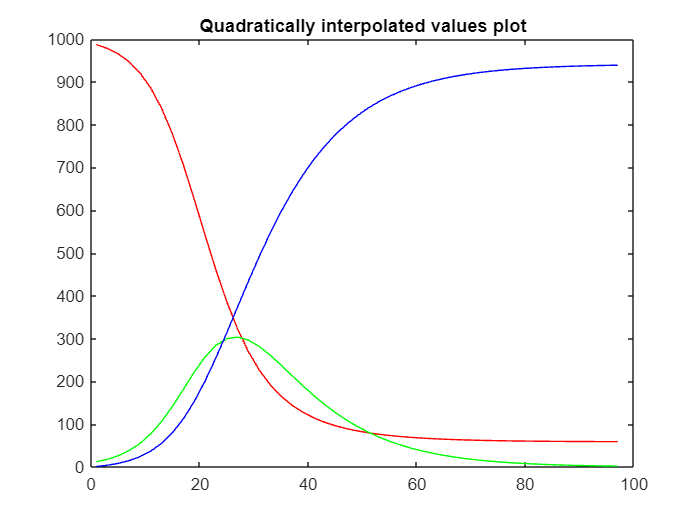


susepInterQuad = zeros(1,size(days,2)); 
infectInterQuad = zeros(1,size(days,2));
recoverInterQuad = zeros(1,size(days,2));


for i=1:n-1  % Quadratic Interpolation for susceptible (flu)
    x = daysInter(1,i);
    x0 = influenza(1,i);
    x1 = influenza(1,i+1);
    x2 = influenza(1,i+2);
    f0 = influenza(2,i);
    f1 = influenza(2,i+1);
    f2 = influenza(2,i+2);

    b0 = (((x-x1)*(x-x2))/((x0-x1)*(x0-x2)))*f0;
    b1 = (((x-x0)*(x-x2))/((x1-x0)*(x1-x2)))*f1;
    b2 = (((x-x0)*(x-x1))/((x2-x0)*(x2-x1)))*f2;
    susepInterQuad(i) = b0 + b1 + b2;
end
for i=1:n-1  % Quadratic Interpolation for infection (flu)
    x = daysInter(1,i);
    x0 = influenza(1,i);
    x1 = influenza(1,i+1);
    x2 = influenza(1,i+2);
    f0 = influenza(3,i);
    f1 = influenza(3,i+1);
    f2 = influenza(3,i+2);

    b0 = (((x-x1)*(x-x2))/((x0-x1)*(x0-x2)))*f0;
    b1 = (((x-x0)*(x-x2))/((x1-x0)*(x1-x2)))*f1;
    b2 = (((x-x0)*(x-x1))/((x2-x0)*(x2-x1)))*f2;
    infectInterQuad(i) = b0 + b1 + b2;
end

for i=1:n-1  % Quadratic Interpolation for recovered (flu)
    x = daysInter(1,i);
    x0 = influenza(1,i);
    x1 = influenza(1,i+1);
    x2 = influenza(1,i+2);
    f0 = influenza(4,i);
    f1 = influenza(4,i+1);
    f2 = influenza(4,i+2);

    b0 = (((x-x1)*(x-x2))/((x0-x1)*(x0-x2)))*f0;
    b1 = (((x-x0)*(x-x2))/((x1-x0)*(x1-x2)))*f1;
    b2 = (((x-x0)*(x-x1))/((x2-x0)*(x2-x1)))*f2;
    recoverInterQuad(i) = b0 + b1 + b2;
end

plot(daysInter(1,1:49), susepInterQuad, 'r')
hold on
plot(daysInter(1,1:49), infectInterQuad, 'g')
plot(daysInter(1,1:49), recoverInterQuad, 'b')
title("Quadratically interpolated values plot")
hold off

EL2susepQuad = sqrt(sum((influenza(2,1:49)-susepInterQuad).^2)./n)  % Error for susceptible (flu)

EL2susepQuad = 16.0362

EL2infectQuad = sqrt(sum((influenza(3,1:49)-infectInterQuad).^2)./n)  % Error for infected (flu)

EL2infectQuad = 8.2915

EL2recoverQuad = sqrt(sum((influenza(4,1:49)-recoverInterQuad).^2)./n)  % Error for susceptible (flu)

EL2recoverQuad = 13.7290

EL2 = [EL2susepLinear EL2infectLinear EL2recoverLinear; EL2susepQuad EL2infectQuad EL2recoverQuad] % 2x3 Matrix (Rows: Linear, Quadratic; Columns: Susceptible, Infected, Recovered)

EL2 =    15.9694   16.0362
    8.2144    8.2915
   13.6982   13.7290
